# Name: Demarce Williams

## Class: Signals and Systems

## Lab #: 07

## Date: October 30, 2025

## Lab 7: Noise Reduction


%  ELLIPTIC LOW-PASS FILTER DESIGN AND SIGNAL ANALYSIS
%  This script:
%   1. Loads and plots the original MATLAB speech signal (mtlb)
%   2. Loads and plots a noisy speech signal
%   3. Compares their spectra
%   4. Designs and applies an elliptic low-pass filter
%   5. Displays results and responses



## 1. SETUP PARAMETERS


Fs = 7418;           % Sampling frequency (Hz)


## 2. LOAD AND PLOT ORIGINAL SIGNAL

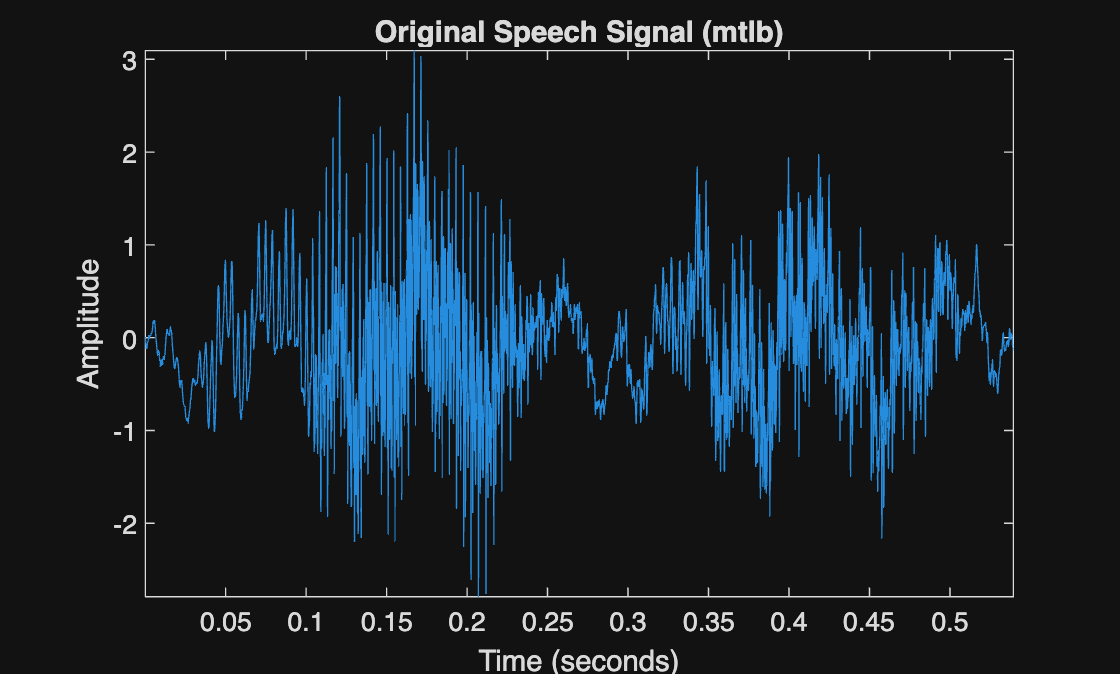


load mtlb;            % Load built-in MATLAB speech signal
L = length(mtlb);     % Length of the signal

figure;
plot((1:L)/Fs, mtlb);
axis tight;
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Original Speech Signal (mtlb)');


% Play the original audio
soundsc(mtlb, Fs);



##  3. LOAD AND PLOT NOISY SIGNAL

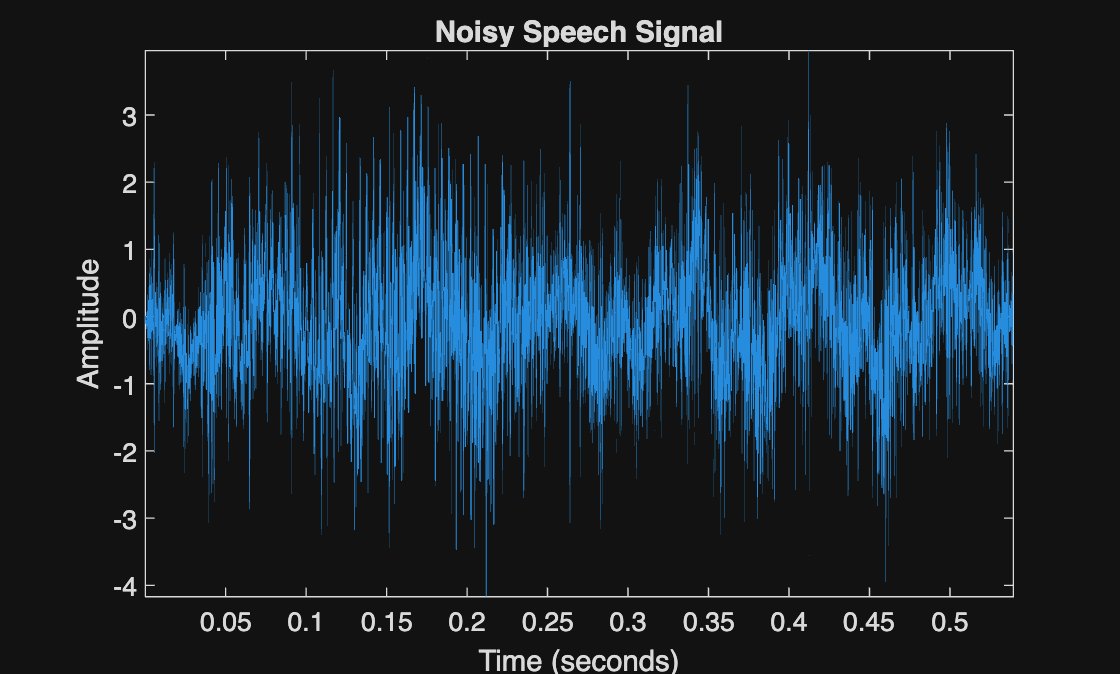


x = load('NoisySpeech.txt');   % Load noisy speech from file

figure;
plot((1:length(x))/Fs, x);
axis tight;
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Noisy Speech Signal');


% Play the noisy audio
soundsc(x, Fs);


## 4. PLOT FREQUENCY SPECTRUM

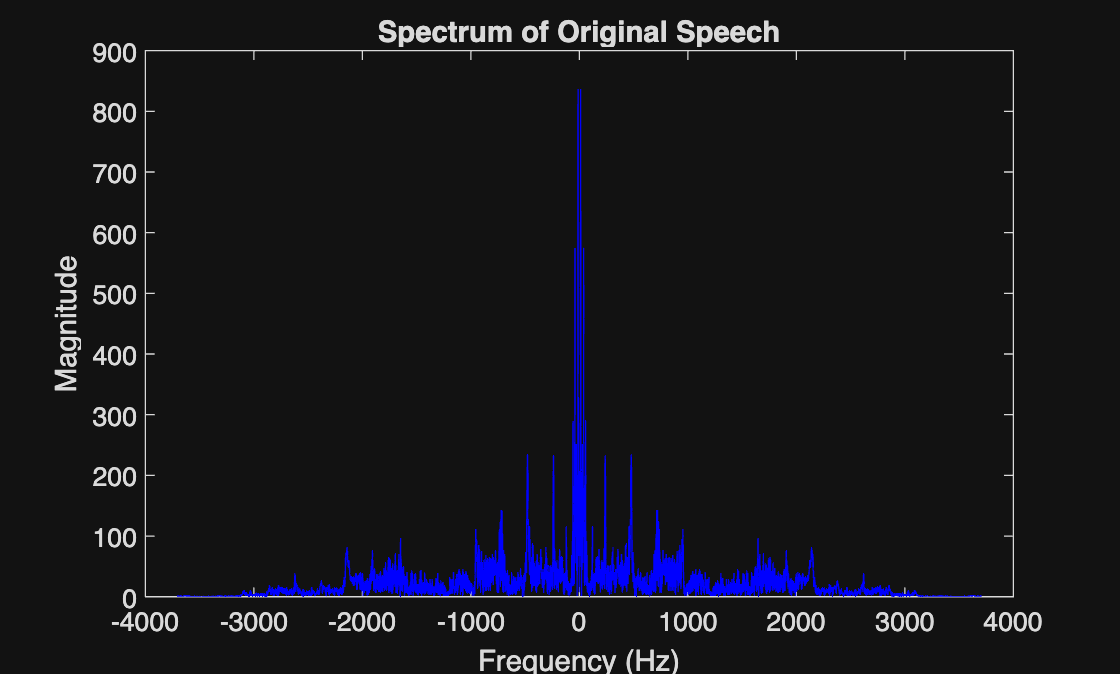

figure;
% Compare the spectra of original and noisy signals
[M1, f1] = dtft(mtlb, 1/Fs);
[M2, f2] = dtft(x, 1/Fs);

figure;
plot(f1, M1, 'b');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Spectrum of Original Speech');


disp('Most of the energy in the mtlb speech signal is concentrated below about 2.5 kHz.');

Most of the energy in the mtlb speech signal is concentrated below about 2.5 kHz.


disp('The strongest components occur mainly below 2 kHz, while higher frequencies above about 3 kHz contain only weak speech energy.');

The strongest components occur mainly below 2 kHz, while higher frequencies above about 3 kHz contain only weak speech energy.


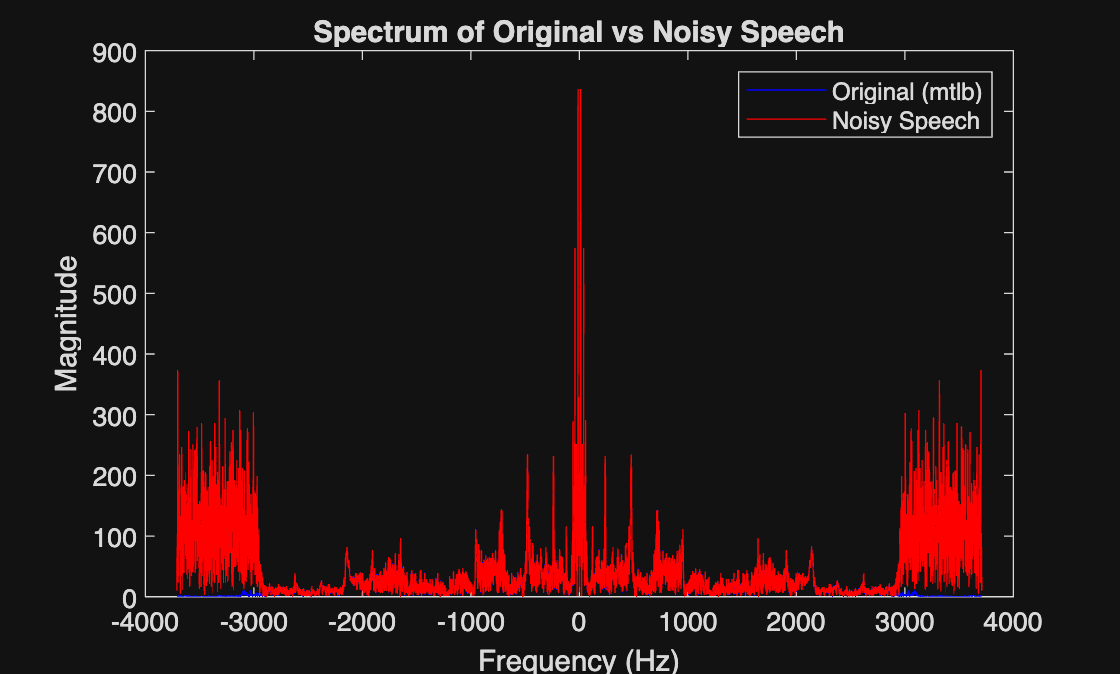



% Compare the spectra of original and noisy signals

[M1, f] = dtft(mtlb, 1/Fs);
figure;
plot(f, M1, 'b');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Spectrum of Original vs Noisy Speech');
hold on;


plot(f, M2, 'r');
legend('Original (mtlb)', 'Noisy Speech');
hold off;


disp('When comparing the spectra of the original and noisy signals, the extra energy at high frequencies in the ');

When comparing the spectra of the original and noisy signals, the extra energy at high frequencies in the 


disp('noisy signal represents the additive noise.');

noisy signal represents the additive noise.


disp('Based on the spectrum, the noise is mainly concentrated above 2.7 kHz.');

Based on the spectrum, the noise is mainly concentrated above 2.7 kHz.


disp('The low-frequency region where both spectra coincide corresponds to the actual speech content, while the high-frequency region, where'); 

The low-frequency region where both spectra coincide corresponds to the actual speech content, while the high-frequency region, where


disp('the noisy signals magnitude rises above that of the clean signal, is dominated by noise.');

the noisy signals magnitude rises above that of the clean signal, is dominated by noise.


## 5. DESIGN ELLIPTIC LOW-PASS FILTER

disp('A lowpass filter allows the low-frequency components (which contain the essential speech information) to pass through while'); 

A lowpass filter allows the low-frequency components (which contain the essential speech information) to pass through while


disp('attenuating the high-frequency components where the noise dominates.');

attenuating the high-frequency components where the noise dominates.


disp('By suppressing these higher frequencies, the filter reduces the noise power, making the speech clearer without greatly affecting'); 

By suppressing these higher frequencies, the filter reduces the noise power, making the speech clearer without greatly affecting


disp('its intelligibility.');

its intelligibility.


disp('The cut-off frequency should be chosen just above the highest significant speech frequency, where the speech energy starts to'); 

The cut-off frequency should be chosen just above the highest significant speech frequency, where the speech energy starts to


disp('fall off and the noise becomes dominant.');

fall off and the noise becomes dominant.


disp('From observation of the spectrum, a cut-off around 2.8 – 3.0 kHz provides a good balance — preserving the speech band while removing'); 

From observation of the spectrum, a cut-off around 2.8 – 3.0 kHz provides a good balance — preserving the speech band while removing


disp('most of the high-frequency noise.');

most of the high-frequency noise.


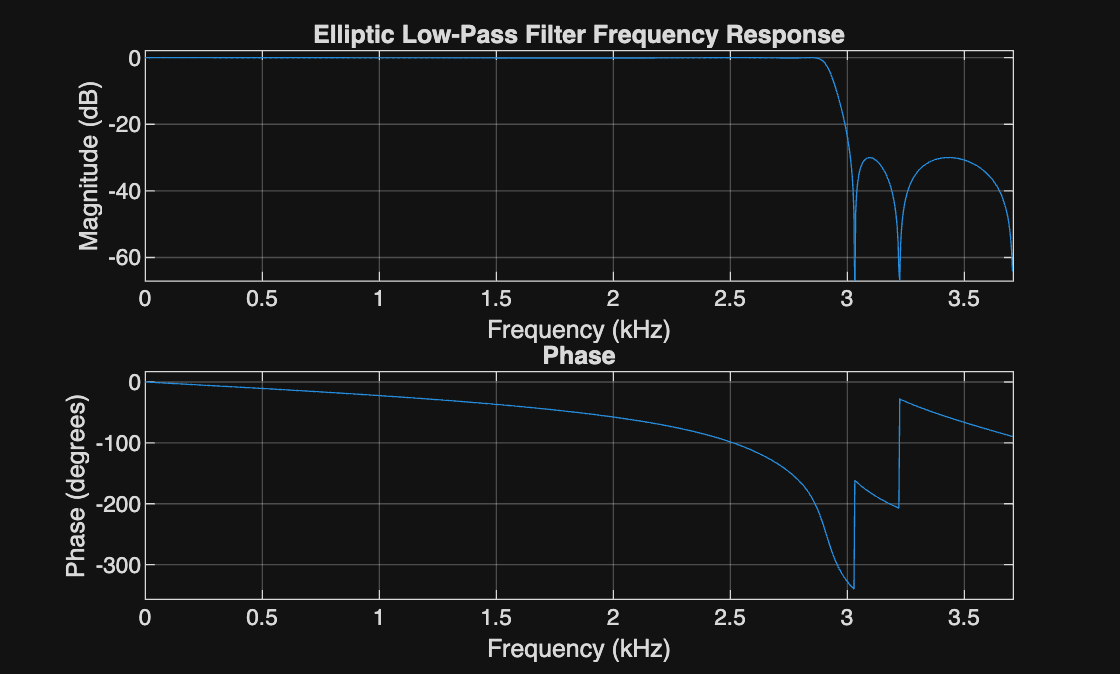



% Filter specifications
Fc = 2867.5;           % Cutoff frequency (Hz)
Rp = 0.1;              % Passband ripple (dB)
Rs = 30;              % Stopband attenuation (dB)
n  = 5;              % Filter order

% Normalized cutoff frequency (relative to Nyquist)
Wn = Fc / (Fs/2);

% Design elliptic low-pass filter
[b, a] = ellip(n, Rp, Rs, Wn, 'low');

% Plot the frequency response of the filter
figure;
freqz(b, a, 1024, Fs);
title('Elliptic Low-Pass Filter Frequency Response');

## 6. APPLY FILTER TO NOISY SIGNAL

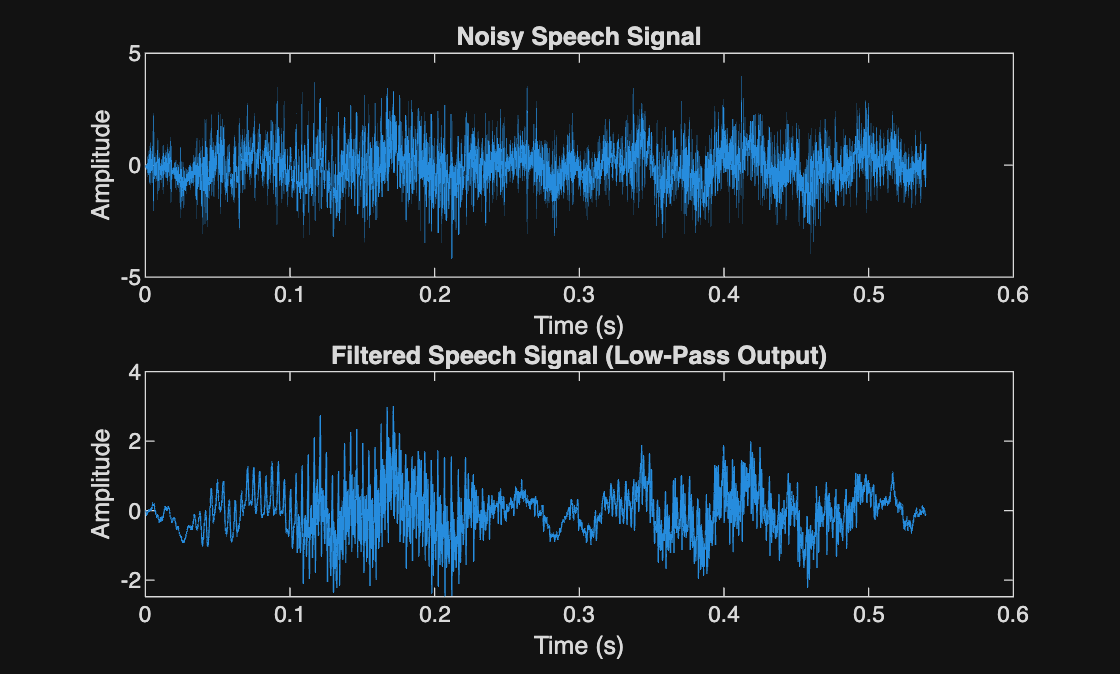


y = filter(b, a, x);   % Filter the noisy signal

% Play the filtered (denoised) speech
soundsc(y, Fs);

% Compare noisy and filtered signals in time domain
figure;
subplot(2,1,1);
plot((1:length(x))/Fs, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('Noisy Speech Signal');

subplot(2,1,2);
plot((1:length(y))/Fs, y);
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered Speech Signal (Low-Pass Output)');

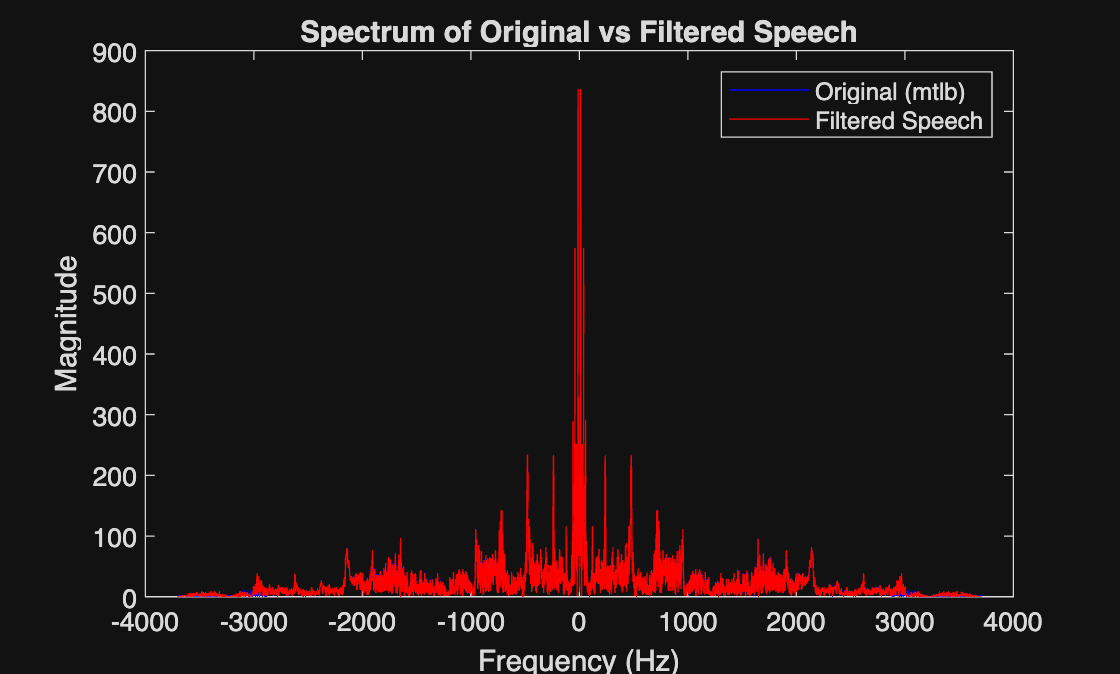


% Compare the spectra of original and filtered signals

[M1, f] = dtft(mtlb, 1/Fs);
figure;
plot(f, M1, 'b');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Spectrum of Original vs Filtered Speech');
hold on;

[M4, f] = dtft(y, 1/Fs);
plot(f, M4, 'r');
legend('Original (mtlb)', 'Filtered Speech');
hold off;

disp('Using an elliptic lowpass filter with a cut-off near 2.9 kHz, most of the high-frequency noise is removed, producing a noticeably'); 

Using an elliptic lowpass filter with a cut-off near 2.9 kHz, most of the high-frequency noise is removed, producing a noticeably


disp('clearer signal.');

clearer signal.


disp('However, because the noise overlaps partially with the speech band, some residual noise remains, and excessive filtering can'); 

However, because the noise overlaps partially with the speech band, some residual noise remains, and excessive filtering can


disp('make the speech sound dull or muffled.');

make the speech sound dull or muffled.



disp('The stop-band ripple (or stop-band attenuation) has a greater effect on noise reduction quality.');

The stop-band ripple (or stop-band attenuation) has a greater effect on noise reduction quality.


disp('A larger stop-band attenuation (smaller ripple) suppresses more of the unwanted high-frequency noise.');

A larger stop-band attenuation (smaller ripple) suppresses more of the unwanted high-frequency noise.


disp('The passband ripple mainly affects the naturalness and fidelity of the speech but has a smaller impact on overall noise level.');

The passband ripple mainly affects the naturalness and fidelity of the speech but has a smaller impact on overall noise level.


disp('Therefore, in this application it is more important that the stopband be close to 0 (strong attenuation) than that the passband be'); 

Therefore, in this application it is more important that the stopband be close to 0 (strong attenuation) than that the passband be


disp('perfectly flat.');

perfectly flat.



disp('The elliptic lowpass filter designed with parameters Fc ≈ 2867.5 Hz, Rp = 0.1 dB, Rs = 30 dB, order = 5 successfully reduces'); 

The elliptic lowpass filter designed with parameters Fc ≈ 2867.5 Hz, Rp = 0.1 dB, Rs = 30 dB, order = 5 successfully reduces


disp('high-frequency noise while maintaining speech intelligibility.');

high-frequency noise while maintaining speech intelligibility.


disp('Increasing stopband attenuation or slightly lowering the cutoff frequency further improves noise suppression at the cost of some loss');  

Increasing stopband attenuation or slightly lowering the cutoff frequency further improves noise suppression at the cost of some loss


disp('in brightness.');

in brightness.
